emb = fastTextWordEmbedding

emb =   wordEmbedding with properties:

     Dimension: 300
    Vocabulary: [1×999994 string]


journalism = word2vec(emb,"journalism")

journalism = 1×300 single row vector
   -0.2462    0.0830    0.1185   -0.0433   -0.1586    0.0733    0.0704    0.2334    0.0188    0.1623   -0.2127   -0.1957   -0.0719    0.0749   -0.0662    0.0144    0.1144   -0.1539   -0.0058   -0.0151   -0.3540    0.0047    0.1127    0.3737   -0.0179   -0.0923   -0.0566   -0.0281    0.2539    0.0054   -0.0354   -0.0851    0.0137    0.0136   -0.1474    0.2228   -0.0722    0.0870    0.0922    0.0638   -0.0669    0.0144   -0.1035   -0.0807   -0.0172    0.1257    0.0864    0.0669   -0.0217    0.1884


editorial = word2vec(emb,"editorial")

editorial = 1×300 single row vector
   -0.1223   -0.1779   -0.0943   -0.0654    0.0603    0.0704    0.0443    0.0989    0.0198    0.1017   -0.1510   -0.1167   -0.0595   -0.1837    0.0134   -0.1742    0.0667    0.0195   -0.1315    0.0227   -0.1091   -0.0388    0.1710   -0.0382    0.0820    0.0883   -0.0642   -0.1963    0.0176   -0.1129   -0.0463   -0.0533   -0.0066   -0.0152   -0.1213   -0.0601   -0.0011    0.1043    0.0999    0.2889   -0.0739    0.0194   -0.0497    0.0135    0.0461   -0.0553   -0.1231    0.0410   -0.0644    0.1476


advertising = word2vec(emb,"advertising")

advertising = 1×300 single row vector
    0.0143   -0.1315    0.0309   -0.2179    0.0283   -0.0990    0.1208    0.2263    0.1210   -0.1625   -0.0694   -0.1919    0.1938    0.0753   -0.1468   -0.1687   -0.0140    0.1650   -0.1372    0.0170   -0.3045    0.0458    0.0464    0.1537   -0.0027    0.0201   -0.0782   -0.0847    0.0598    0.0169   -0.0809    0.0083   -0.1768   -0.1289   -0.0829    0.0123   -0.0471    0.0547   -0.0059   -0.0202   -0.1380   -0.1427   -0.1421   -0.0774    0.0678   -0.0056    0.0967    0.1359   -0.2745   -0.0854


vec = journalism - editorial - advertising

vec = 1×300 single row vector
   -0.1382    0.3924    0.1819    0.2400   -0.2472    0.1019   -0.0947   -0.0918   -0.1220    0.2231    0.0077    0.1129   -0.2062    0.1833    0.0672    0.3573    0.0617   -0.3384    0.2629   -0.0548    0.0596   -0.0023   -0.1047    0.2582   -0.0972   -0.2007    0.0858    0.2529    0.1765    0.1014    0.0918   -0.0401    0.1971    0.1577    0.0568    0.2706   -0.0240   -0.0720   -0.0018   -0.2049    0.1450    0.1377    0.0883   -0.0168   -0.1311    0.1866    0.1128   -0.1100    0.3172    0.1262


(journalism) - (editorial) - (advertising) =...

word = vec2word(emb,vec)

word = "Oersted"

words = emb.Vocabulary(1:5000);
V = word2vec(emb,words);
size(V)

ans =         5000         300


XY = tsne(V);

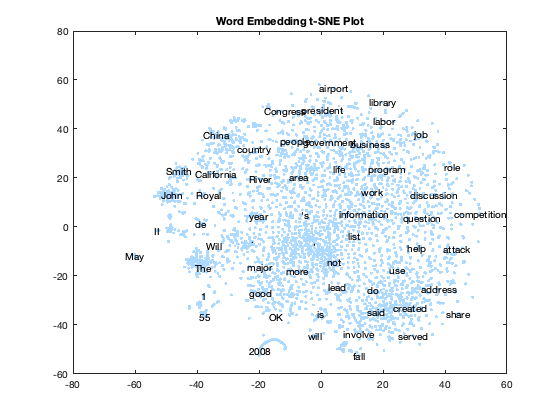

figure 
textscatter(XY,words)
title("Word Embedding t-SNE Plot")

zoom

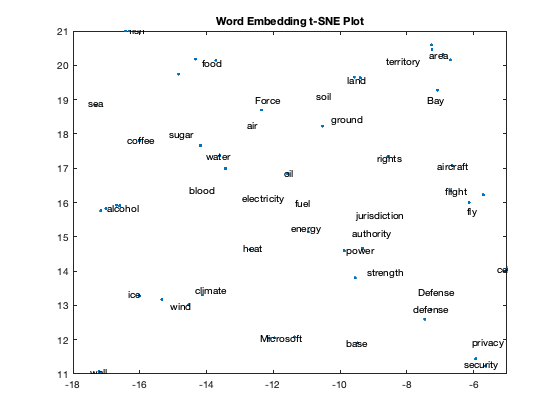

xlim([-18 -5])
ylim([11 21])

3D

words = emb.Vocabulary(1:5000);
V = word2vec(emb,words);
size(V)

ans =         5000         300


XYZ = tsne(V,'NumDimensions',3);

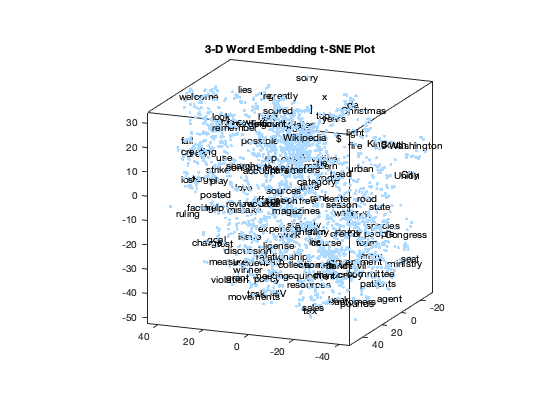

figure 
ts = textscatter3(XYZ,words);
title("3-D Word Embedding t-SNE Plot")

copygraphics(ts,'ContentType','vector')

zoom

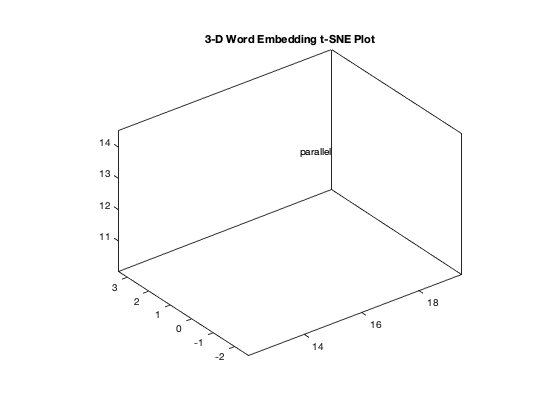

xlim([12.04 19.48])
ylim([-2.66 3.40])
zlim([10.03 14.53])

cluster analysis

words = emb.Vocabulary(1:5000);
V = word2vec(emb,words);
size(V)

ans =         5000         300


cidx = kmeans(V,25,'dist','sqeuclidean');

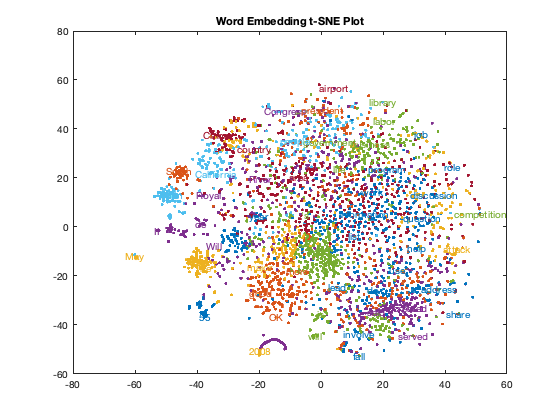

figure
textscatter(XY,words,'ColorData',categorical(cidx));
title("Word Embedding t-SNE Plot")

zoom

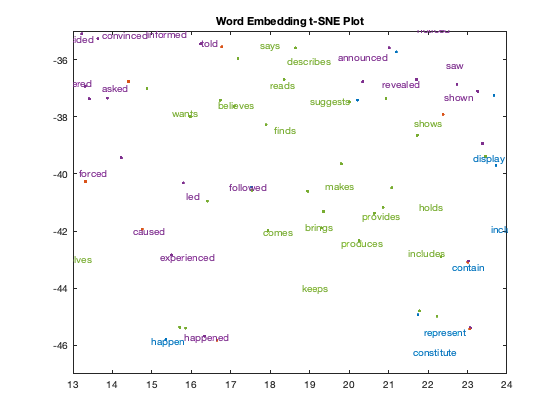

xlim([13 24])
ylim([-47 -35])